# Burst photography example

Burst photograph has become common. Here is an example of combining multiple exposures of the same duration in ISETCam. This case is simple because there is no motion in the scene. For general burst photography, objects (and the camera) move and the full algorithm has to include alignment code.

Wandell, 2019

Livescript conversion & burst comparisons, Cardinal, 2020

See also sensorComputeMEV, t_sensorMultipleExposure

ieInit
wbState = ieSessionGet('waitbar');
ieSessionSet('waitbar',false);  % Dealing with a waitbar/Matlab issue.

## Set up the default scene and the oi

We can use an HDR scene or an RGB image.

scene = sceneCreate;
%scene = sceneFromFile('Feng_Office-hdrs.mat','multispectral');
% sceneWindow(scene); sceneSet(scene,'display mode','hdr');
oi = oiCreate; oi = oiCompute(oi,scene);

## Run the sensor simulation

First in auto exposure mode.  Kind of a lousy rendering of the image.

% Create a default sensor and set it to our scene FOV
sensor = sensorCreate; 
sensor = sensorSet(sensor,'fov',sceneGet(scene,'fov'),oi);

sensorAE = sensorSet(sensor,'name','Single-frame, Auto exposure');
sensorAE = sensorSet(sensorAE,'noise flag',2); % the default -- full noise 
sensorAE = sensorCompute(sensorAE,oi);

Line is (x,y), not row,col.  (1,1) is upper left corner. 

The bright region is the window in the image.

showLine      = 10

showLine = 10

fprintf("Voltage on Line %d Single-shot AE Setting:", showLine);

Voltage on Line 10 Single-shot AE Setting:

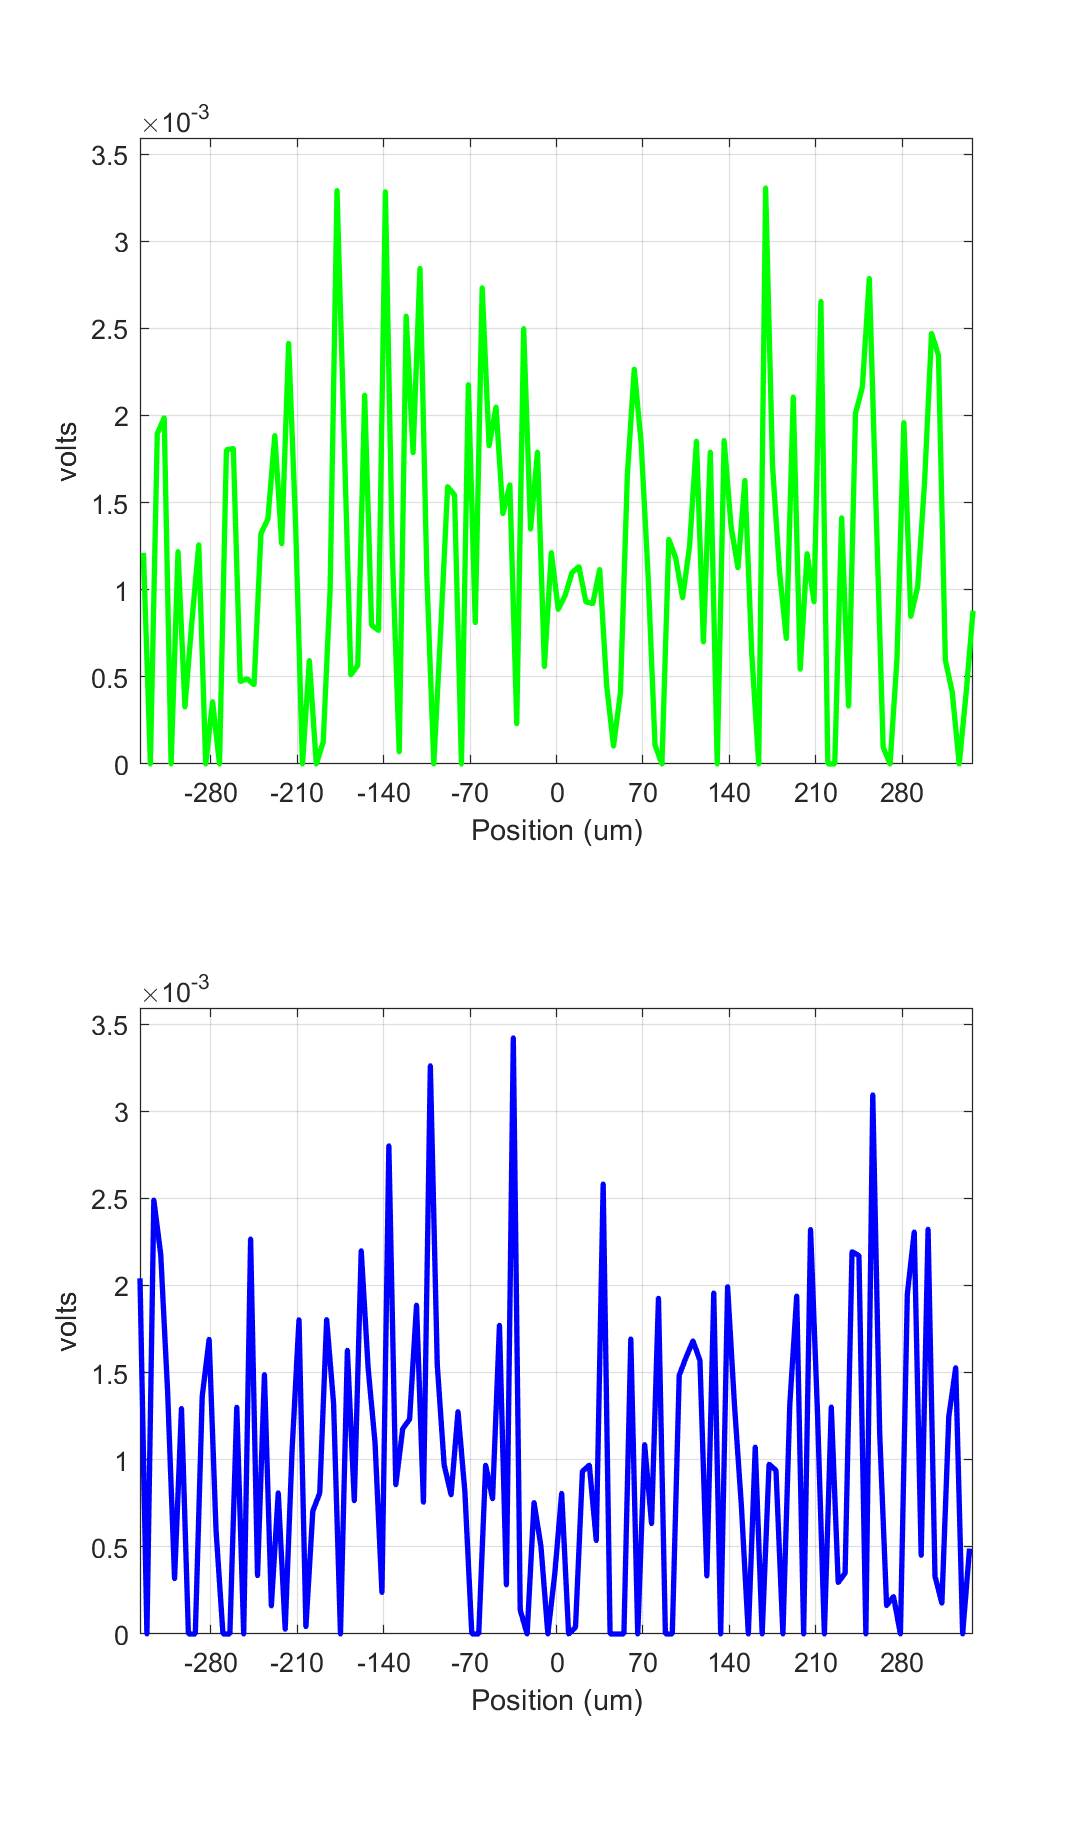

sensorPlot(sensorAE,'volts hline',[1,showLine]);
sensorWindow(sensorAE);

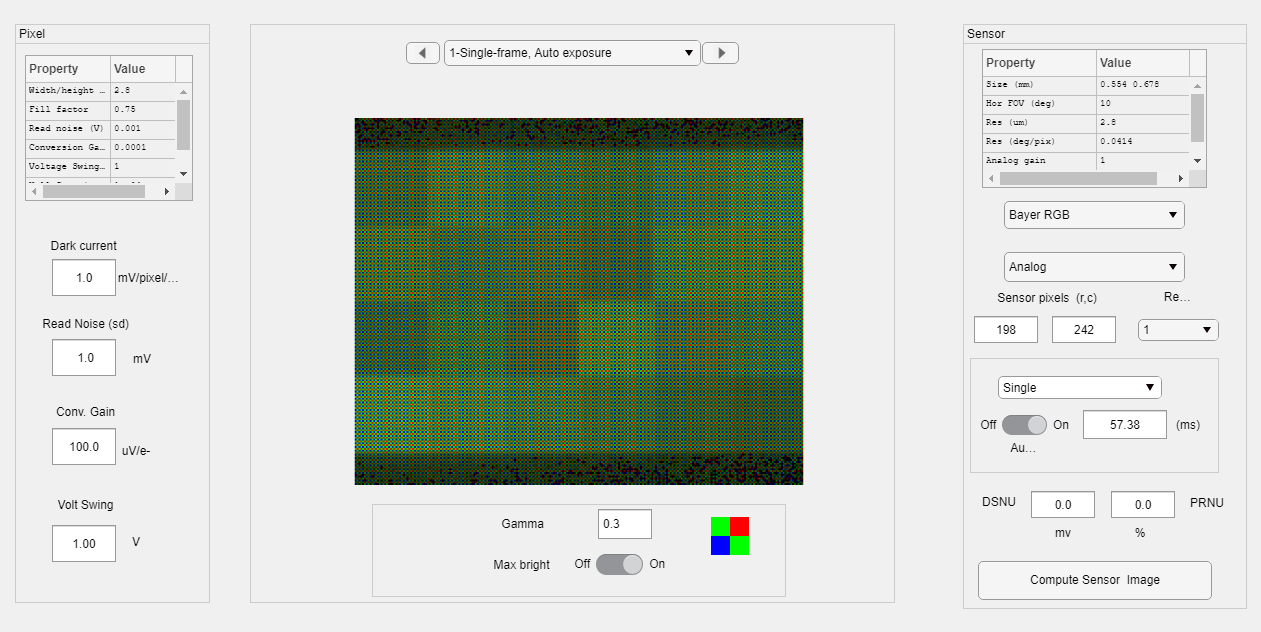

% we do this after the AE version to change the burst gamma?
sensorSet(sensor,'gamma',0.3);

## Now operate the sensor in burst mode

We'll experiment with the default noise setting, and then turn off all the sensor noise, but there is still some other remaining noise.

Use the slider to control how many images to take in a burst. Notice the effect of using more or fewer frames on noise.

numImages     = 20

numImages = 20

expTime     = autoExposure(oi,sensor)/numImages; % was fixed at 4, but seems like it should vary in some way
burstTiming = repmat(expTime,1,numImages);

sensorBurst = sensorSet(sensor,'exp time',burstTiming);
sensorBurst = sensorSet(sensorBurst,'noise flag',2); % the default -- full noise 
sensorBurst = sensorSet(sensorBurst,'name',sprintf('burst-default-noise-%d-frames',numel(burstTiming)));
sensorBurst = sensorCompute(sensorBurst,oi);
sensorBurst = sensorSet(sensorBurst,'exp time',burstTiming(1)); % set back
%sensorWindow(sensorBurst);

Now build a low-noise version of the sensor:

sensorBurstLN = sensorSet(sensor,'exp time',burstTiming);
sensorBurstLN = sensorSet(sensorBurstLN,'noise flag',-1); % turn sensor noise off
sensorBurstLN = sensorSet(sensorBurstLN,'name',sprintf('burst-low-noise-%d-frames',numel(burstTiming)));
sensorBurstLN = sensorCompute(sensorBurstLN, oi);
sensorBurstLN = sensorSet(sensorBurstLN,'exp time',burstTiming(1));
% sensorWindow(sensorBurstLN);

Currently we simply average the voltage from each image capture of our default noise and low-noise burst sensors:

volts = sensorGet(sensorBurst, 'volts');
volts = mean(volts,3)*numImages;
sensorBurst = sensorSet(sensorBurst,'volts',volts);
sensorWindow(sensorBurst);

% Line is (x,y), not row,col.  (1,1) is upper left corner.
fprintf("Voltage on Line %d Default-Noise Burst Setting:", showLine);

Voltage on Line 10 Default-Noise Burst Setting:

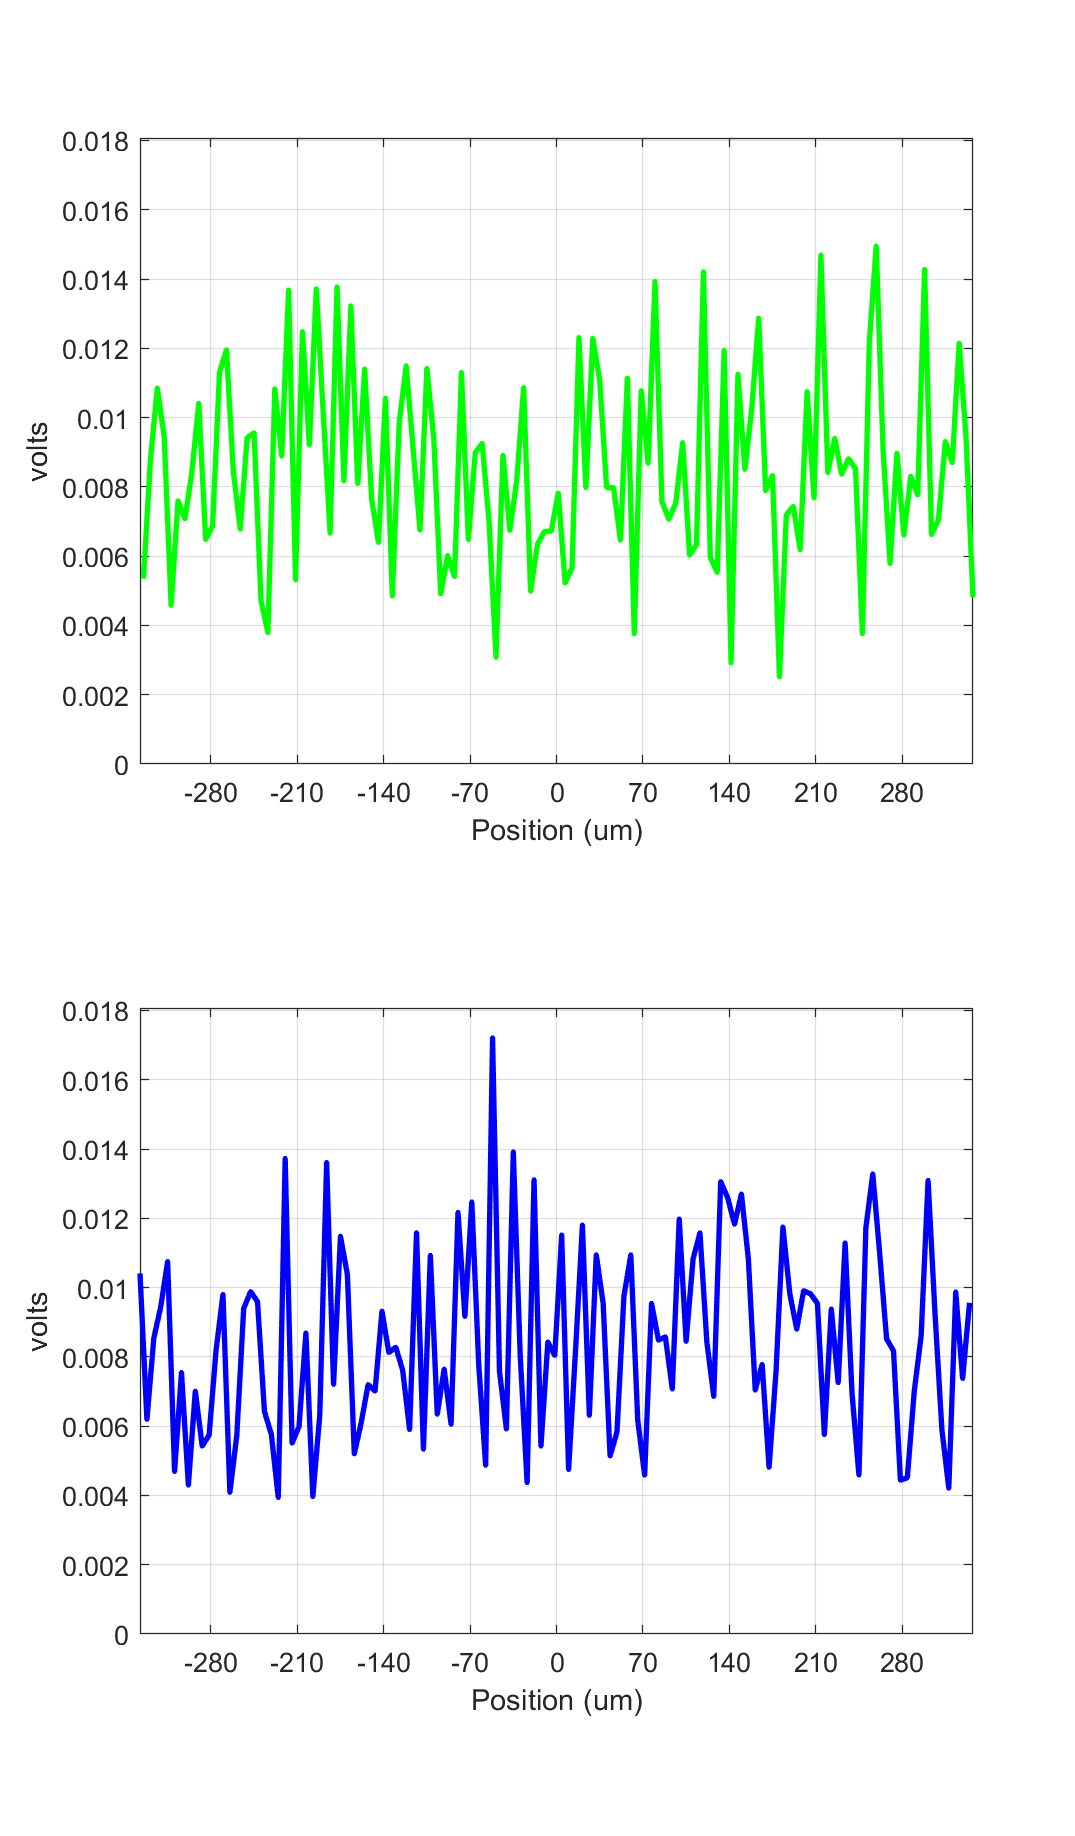

sensorPlot(sensorBurst,'volts hline',[1,showLine]);

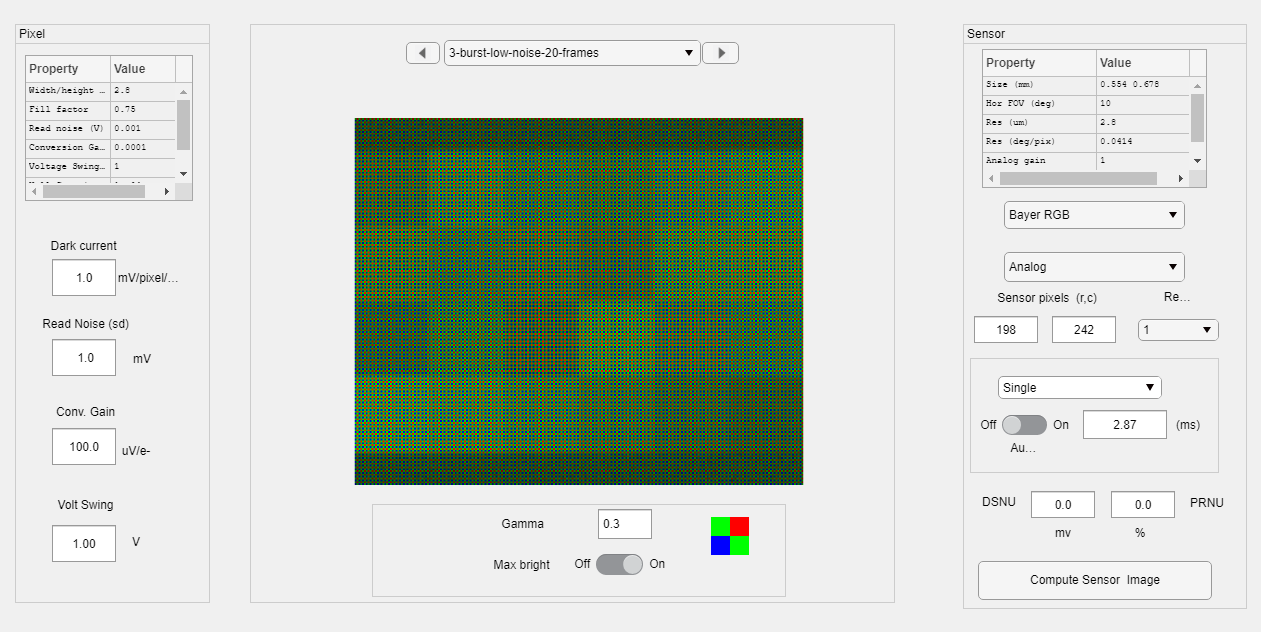

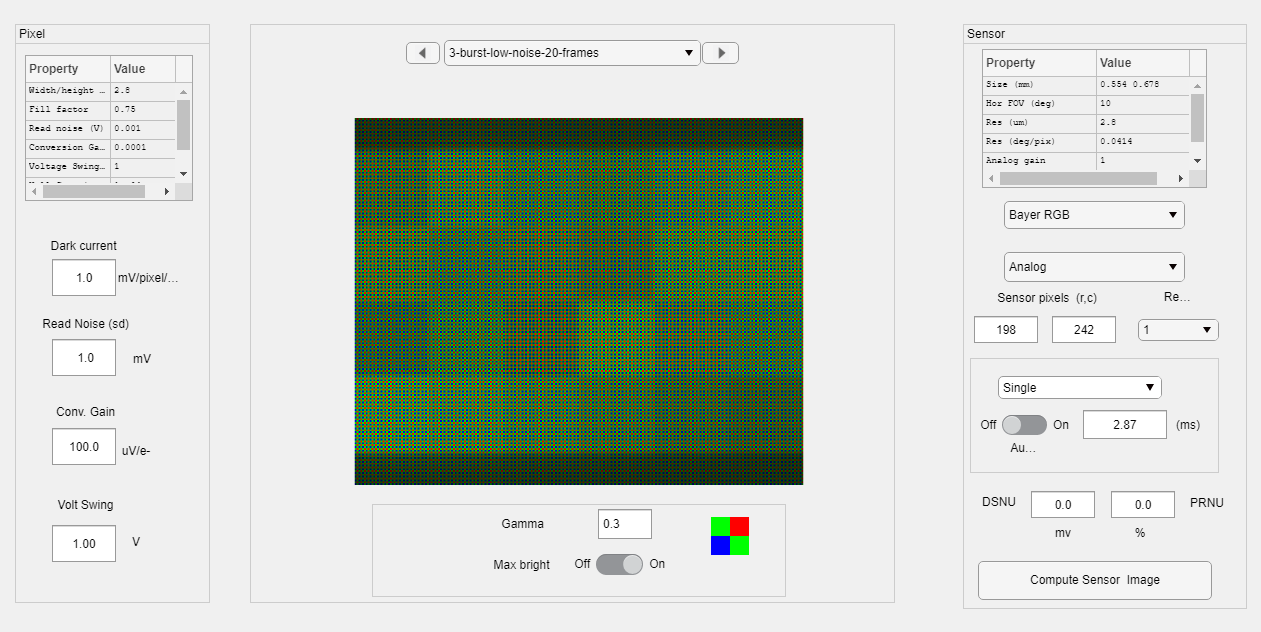


voltsLN = sensorGet(sensorBurstLN,'volts');
voltsLN = mean(voltsLN,3)*numImages;
sensorBurstLN = sensorSet(sensorBurstLN,'volts',voltsLN);
sensorWindow(sensorBurstLN);


% Line is (x,y), not row,col.  (1,1) is upper left corner.
fprintf("Voltage on Line %d Low-Noise Burst Setting:", showLine);

Voltage on Line 10 Low-Noise Burst Setting:

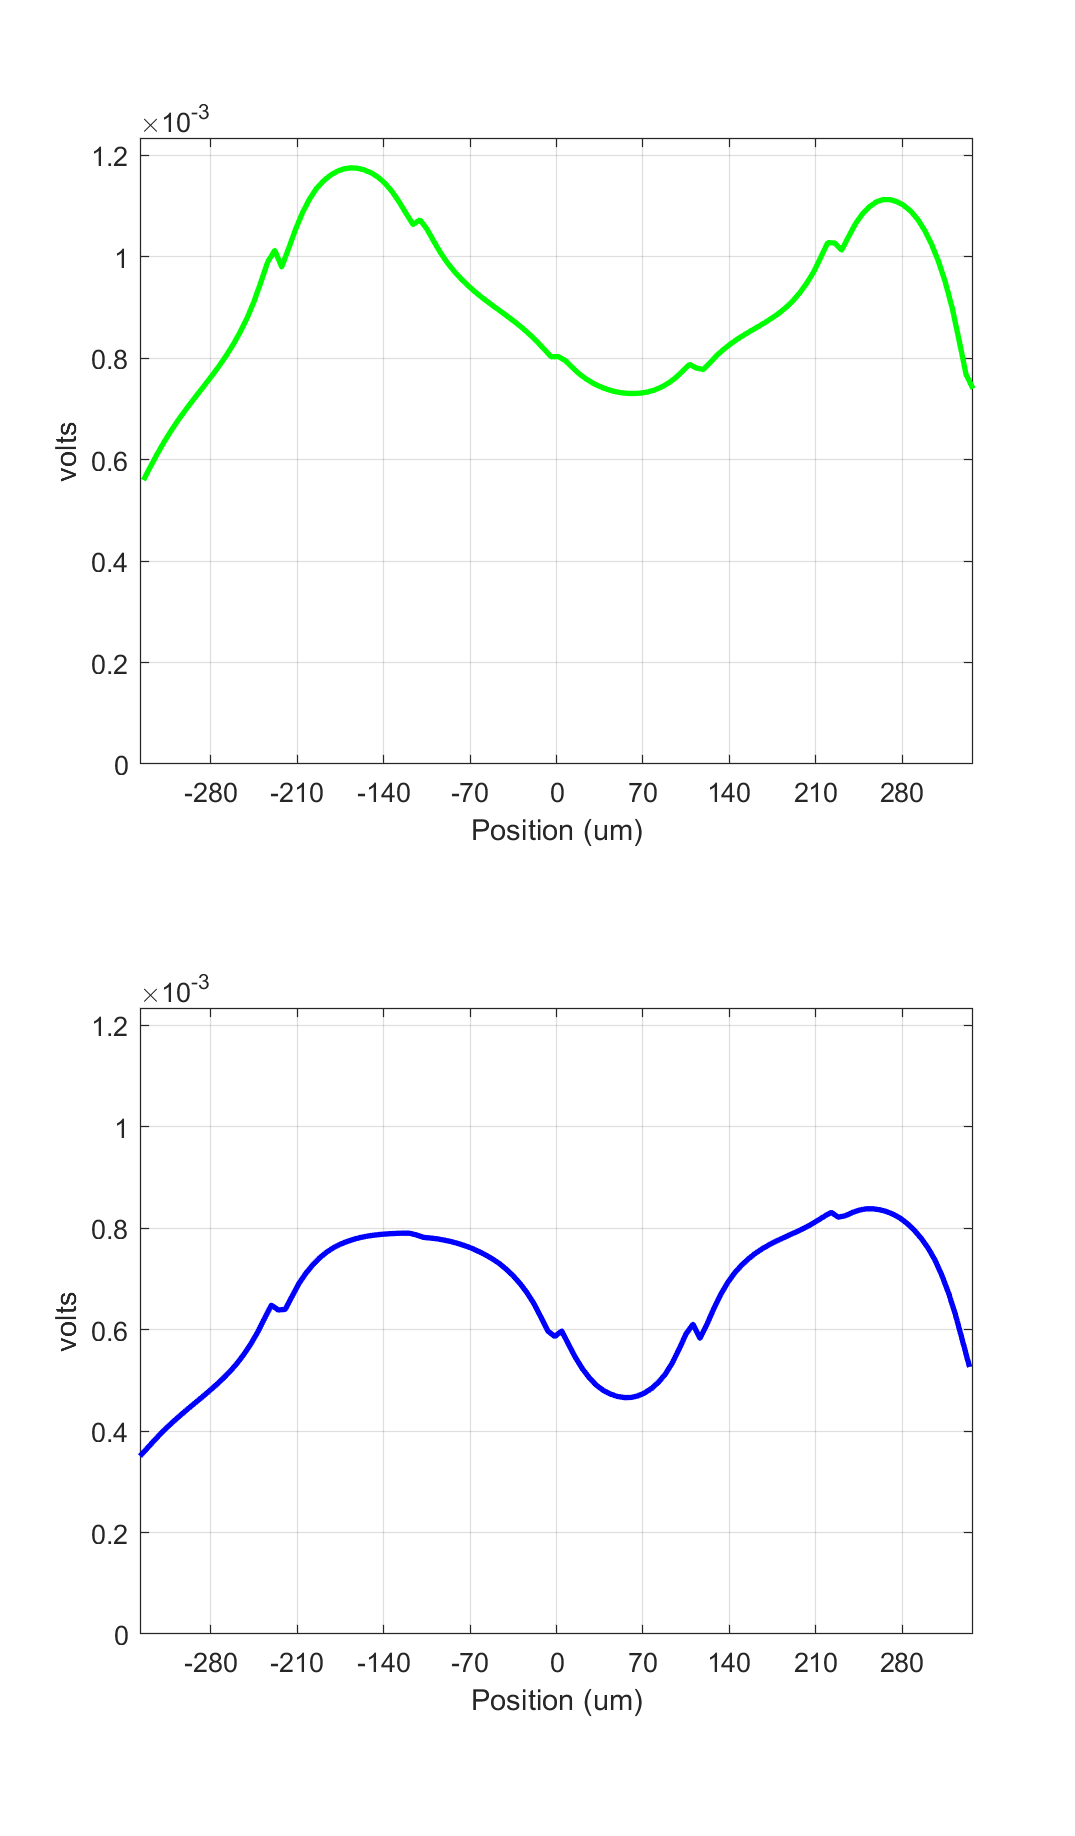

sensorPlot(sensorBurstLN,'volts hline',[1,showLine]);

## Convert through image processing

We use the same IP for all three sensor versions (single-shot AE, Default-noise model Burst, and Low-Noise Burst). 

ip = ipCreate;
ip = ipSet(ip, 'render demosaic only', 'true');
ip = ipCompute(ip, sensorAE);
%rgb = ipGet(ip, 'srgb');
%rgb = hdrRender(rgb);
%ieNewGraphWin; imagescRGB(rgb);
ipWindow(ip);

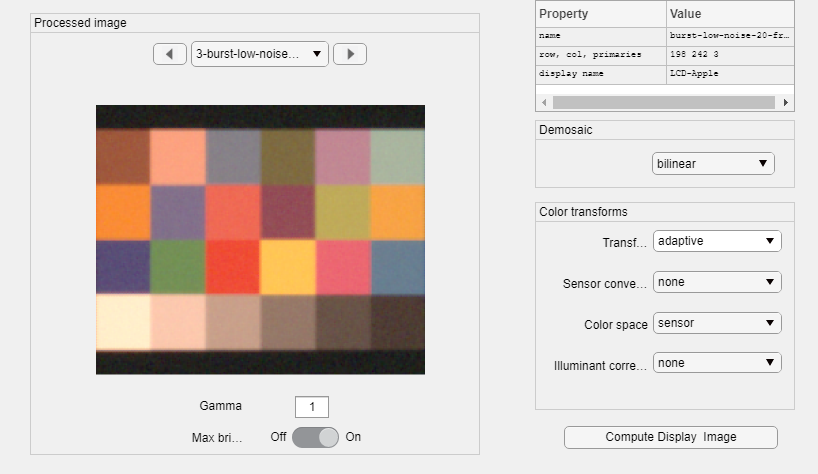

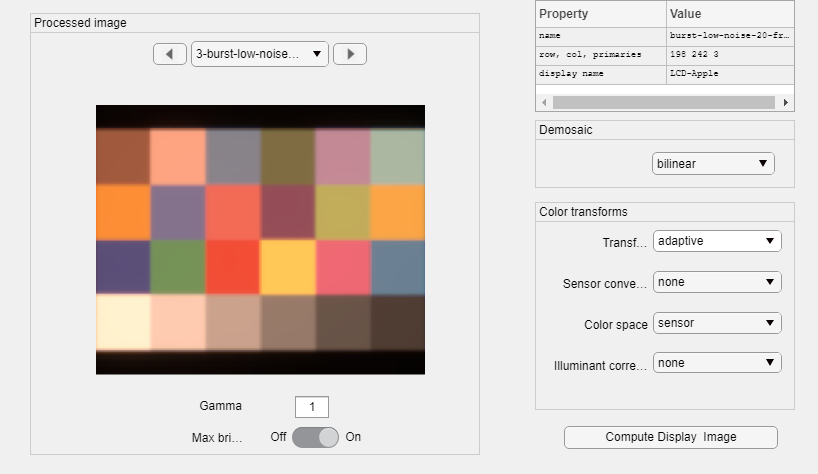


ipBurst  = ipCreate;
ipBurst = ipSet(ipBurst, 'render demosaic only', 'true');
ipBurst  = ipCompute(ipBurst,sensorBurst);
%rgbBurst = ipGet(ipBurst,'srgb');
%rgbBurst = hdrRender(rgbBurst);
%ieNewGraphWin; imagescRGB(rgbBurst);
ipWindow(ipBurst);

ipLN  = ipCreate;
ipLN = ipSet(ipLN, 'render demosaic only', 'true');
ipLN  = ipCompute(ipLN,sensorBurstLN);
%rgbLN = ipGet(ipLN,'srgb');
%rgbLN = hdrRender(rgbLN);
%ieNewGraphWin; imagescRGB(rgbLN);
ipWindow(ipLN);


ieSessionSet('waitbar',wbState);  % Dealing with a waitbar/Matlab issue.